## fv3

In this scrip, i try to use fitness function to directily get parameter of GLENII.

## Import data and previewing

The data come from expomential fitness data.

data_name='p47';
selecting_curve='xy';
experiment_interval=5;
min_length=51;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.046e+05;%p47_5s
a(2)=0.0004364;
a(3)=-7.307e+04;
a(4)=-0.03125;

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);


## Parameter importing

kB=1.3806505e-23;
T=293;%confirmed

GLE_input=[4.65655716413280e-08,	2.03557372171703e-07,	0.789712554876253];

%m=GLE_input(1);
%psi=GLE_input(2);
mpsi=GLE_input(1);
zeta=GLE_input(2);
H=GLE_input(3);

## Fitness

%init para
para0=[6.7610e-08,8.8444e-07,0.59222];
p = lsqcurvefit(@(p, t) GLENII_get_MSD(p(1),p(2),p(3),t), para0, t, interceptive_experiment_MSD);


Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>


MSD_fit_lsq = GLENII_get_MSD(p(1),p(2),p(3), t)

MSD_fit_lsq = 	1.0e+-12 *

    0.0283    0.0445    0.0562    0.0652    0.0722    0.0780    0.0826    0.0865    0.0898    0.0926    0.0950    0.0970    0.0988    0.1004    0.1018    0.1030    0.1040    0.1050    0.1058    0.1066    0.1073    0.1079    0.1085    0.1090    0.1095    0.1099    0.1103    0.1107    0.1111    0.1114    0.1117    0.1119    0.1122    0.1124    0.1127    0.1129    0.1131    0.1133    0.1134    0.1136    0.1138    0.1139    0.1141    0.1142    0.1143    0.1144    0.1146    0.1147    0.1148    0.1149


## Plotting

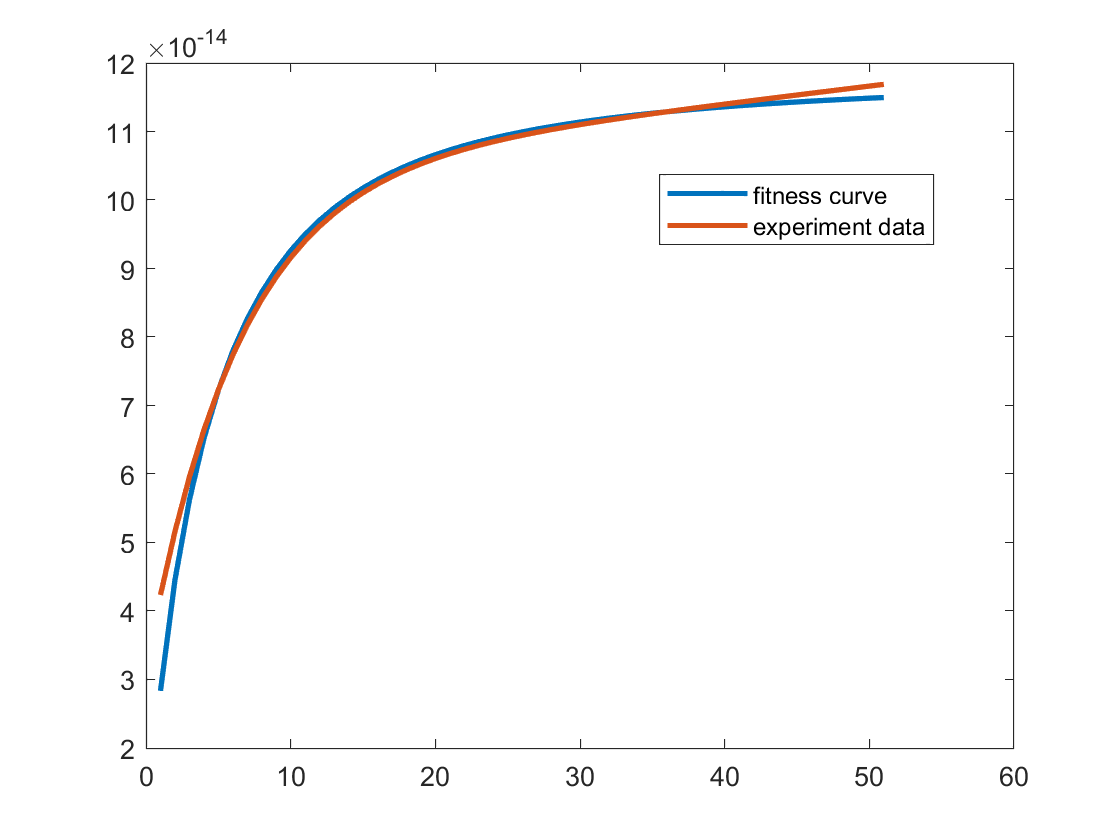

figure
plot(MSD_fit_lsq,'LineWidth',2,"DisplayName",'fitness curve');
hold on
plot(interceptive_experiment_MSD,'LineWidth',2,"DisplayName",'experiment data');
legend("Location","best")